20180202

How to choose the AR(p) time series?

the threshold is only related to the length of the time series.

close all;
clear;
clc;

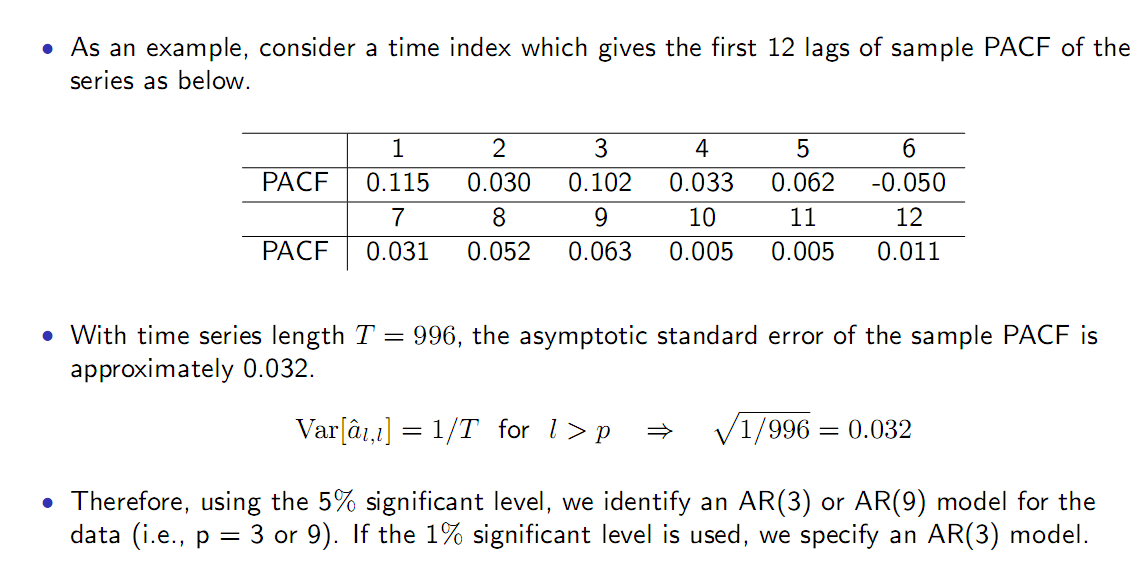

PACF = [0.115,0.030,0.102,0.033,0.062,-0.050,0.031,0.052,0.063,0.005,0.005,0.011];
T = 996; % length of time series
var_a = 1/T; % asymototic variance of a^l
sta_a = sqrt(var_a); % asymototic standard error of a^l
side_mod = 'double';
sig_lev = 0.05; % significant level 5%
switch side_mod
    case 'double'
        thr = norminv(sig_lev/2); % threshold of significant level
                                  % same as norminv(0.05/2,0,1)
                                  % inverse of normcdf!!!
    case 'single'
        thr = norminv(sig_lev); % threshold of significant level
end

%{
if strcmp(side_mod, 'double') % double side
    t = -3:0.001:3;
    b = normpdf(t,0,1);
    figure,
    plot(t,b);
    %{
    hold on;
    plot([thr,thr],[0,normpdf(thr)]); % the pack line
    hold on;
    plot([-thr,-thr],[0,normpdf(-thr)]); % the pack line
    %}
    hold on;
    ar = area(t(t<=thr),b(t<=thr));
    ar.FaceColor = 'r';
    hold on;
    ar = area(t(t>=-thr),b(t>=-thr));
    ar.FaceColor = 'r';
    %{
    t1 = -3:0.001:thr;
    b1 = find(abs(b-normpdf(thr))<0.0001);
    area(t1,b(1:min(b1)));
    hold on;
    t2 = -thr:0.001:3;
    area(t2,b(max(b1):end));
    %}
    hold off;
end
%}

thr_f = abs(thr*sta_a); % the final threshold
ACF = PACF;
ACF(abs(PACF)<thr_f) = 0;


























